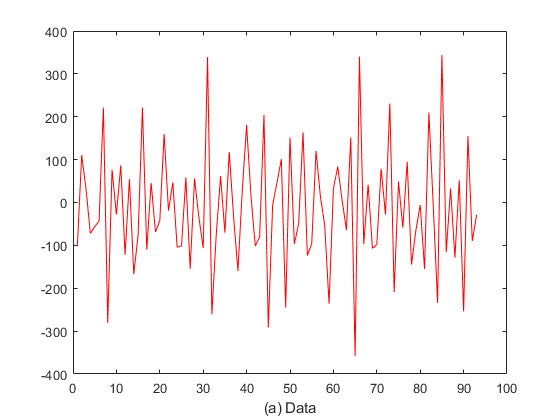

clear all;
close all;

fin = fopen('joe.dat');
data = fscanf(fin,'%f');
fclose(fin);
plot(data,'r');
xlabel('(a) Data');

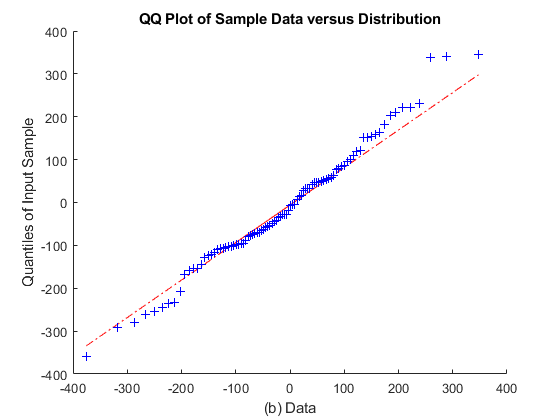

std_gauss = fitdist(data,"Normal");
qqplot(data,std_gauss);
xlabel('(b) Data');

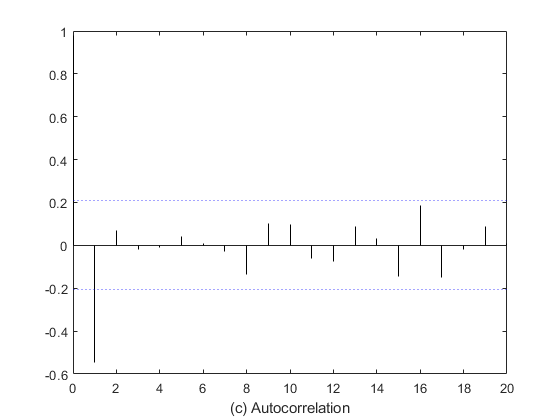

[acf,lags,bounds] = autocorr(data);
stem(lags,acf,'Marker','none','Color','k');
xlabel('(c) Autocorrelation');
hold on
yline(bounds(1),':b');
hold on
yline(bounds(2),':b');
hold off

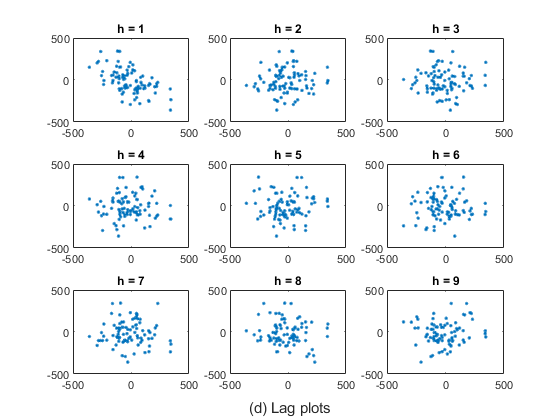

fig = figure;
for i=1:9
    shifted_data = lagmatrix(data,i);
    subplot(3,3,i);
    plot(data,shifted_data,'.');
    title(['h = ' num2str(i)]);
    axs = axes(fig,'Visible','off');
    axs.XLabel.Visible = 'on';
    xlabel('(d) Lag plots');
end